# Filled Line Chart Example

Plots a line chart with a filled gradient using explicit triangulation for optimization.

### Graph a sine curve with a filled gradient.

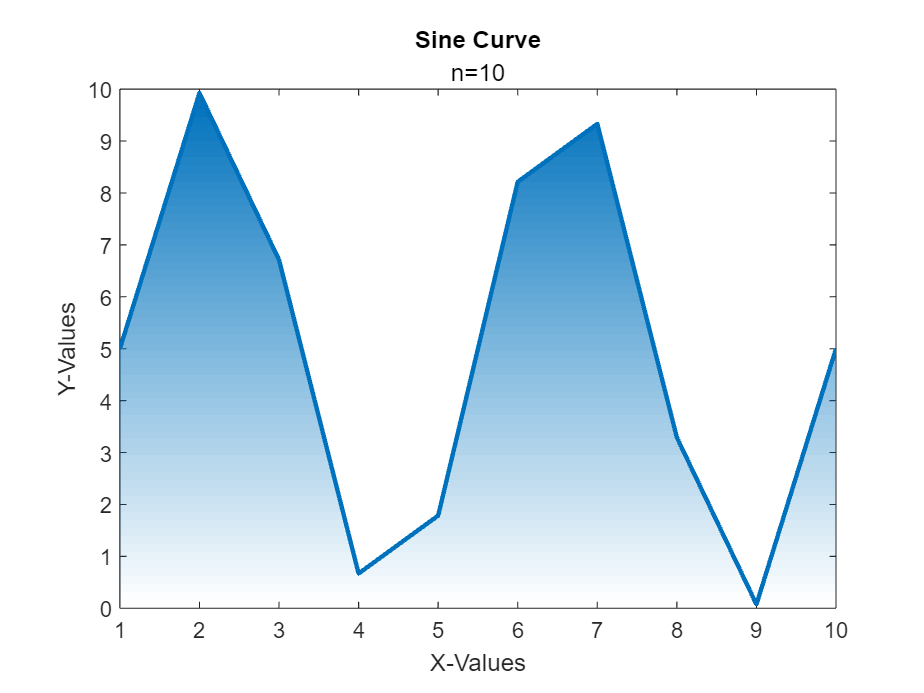

n = 10;
x = 1:n;
y = 5*sin(linspace(0,4*pi,n)) + 5;

f = filledLineChart(x,y);
f.Title = "Sine Curve";
f.Subtitle = "n=10";
f.XLabel = "X-Values";
f.YLabel = "Y-Values";

Notice that we are explicitly drawing out the traingles in the optimized algorithm. To see it clearly, set ShowTriangulation to true. This is opposed to the typical approach of just drawing out the line.

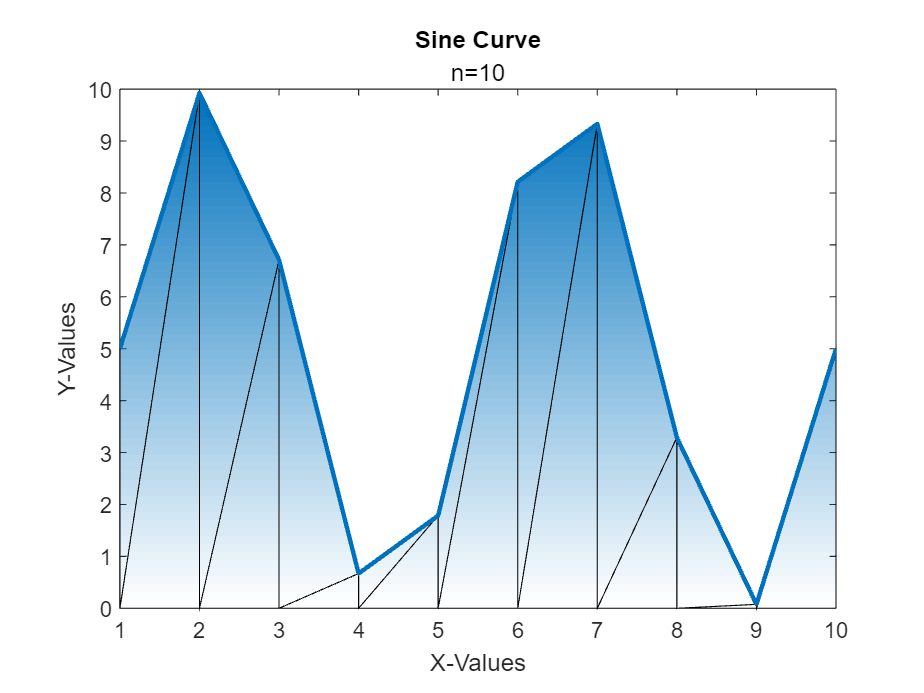

f.ShowTriangulation = true;

Explicit triangulation makes a massive difference in scalability and efficiency. The performanceTest.m file lets you observe the time difference between using the optimized algorithm and the unoptimized one as we steadily increase *n. *It is not part of the livescript due to the time it takes to run.

To plot multiple lines, a sine and cosine curve, provide the new YData as two columns.

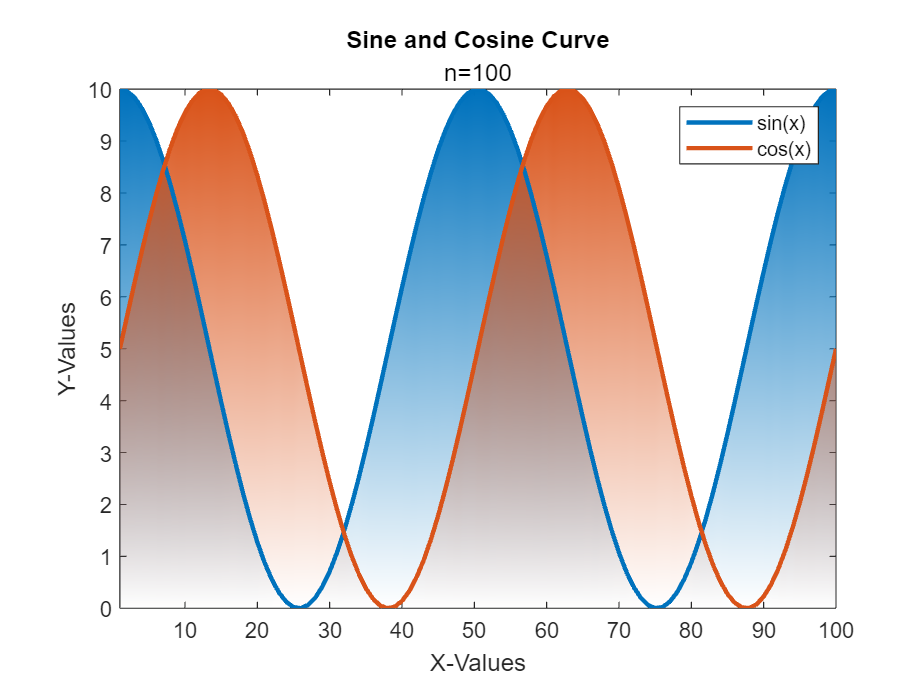

n = 100;
x = 1:n;
y = 5*sin(linspace(0,4*pi,n)) + 5;
y2 = 5*cos(linspace(0,4*pi,n)) + 5;
g = filledLineChart(x,[y' y2'], 'LegendVisible', true, 'LegendLabels', ["sin(x)"; "cos(x)"]);
g.Title = "Sine and Cosine Curve";
g.Subtitle = "n=100";
g.XLabel = "X-Values";
g.YLabel = "Y-Values";

Notice that line style and line width apply to all lines in the axes.

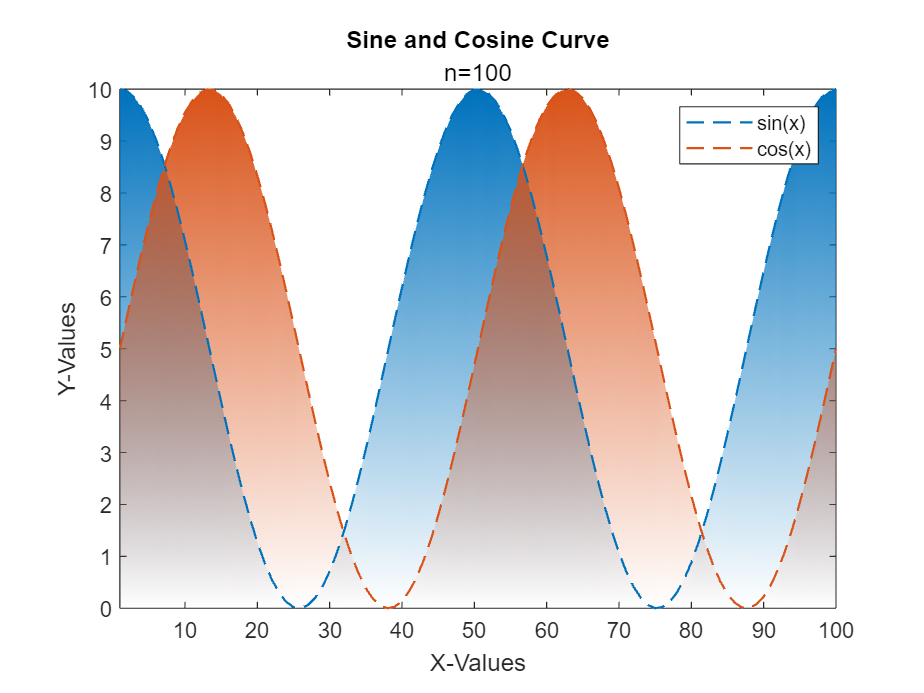

g.LineStyle = '--';
g.LineWidth = 1;

We can plot the same lines using the unoptimized algorithm as well.

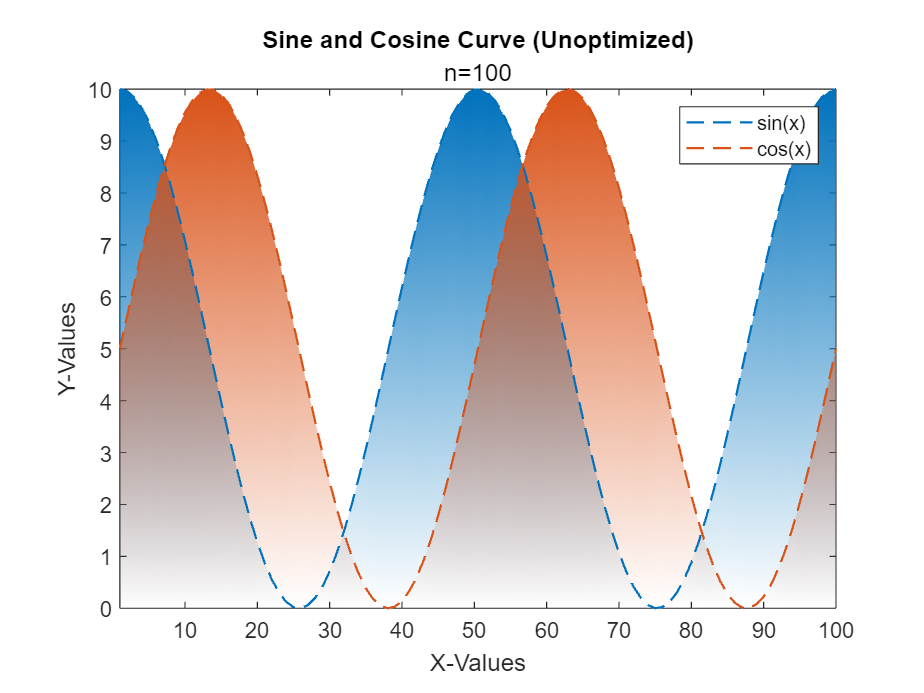

g.Optimized = false;
g.Title = g.Title + " (Unoptimized)";